## 2.1 Probabilidade condicional, independência

**1. Considere familias com filhos em que a probabilidade de nascimento de rapazes é igual à de nascimento de raparigas:**

(a) Obtenha por simulacao uma estimativa da probabilidade do acontecimento “ter pelo menos um filho rapaz" em familias com 2 filhos

p = 0.50;
N = 1e5;

experiencias = rand(2,N)>p;

CF = sum(experiencias)>=1;
CP = N;
prob = sum(CF)/CP

prob = 0.7503

(b) Determine o valor teórico do acontecimento da alínea anterior e compare-o com a estimativa obtida por simulacao. Os valores sao iguais? Porquê?

n = 2;
for k = [1 2]
    probArray(k) = nchoosek(n,k)*p^k*(1-p)^(n-k);
end
finalProb = sum(probArray)

finalProb = 0.7500

%% Os valores não são iguais, mas sim muito próximos,
%% pois o valor teórico é uma constante, enqaunto que
%% o valor prático depende de amostras que são criadas
%% aleatoriamente, logo o resultado prático está sempre
%% sujeito a alterações.


(c) Suponha que para uma família com 2 filhos escolhida ao acaso, sabemos que um dos filhos é rapaz. Qual a probabilidade do outro filho ser também rapaz? Determine o valor teórico desta probabilidade e estime a mesma probabilidade por simulação.

%% Casos Favoráveis: HH
%% Casos Possíveis: HH , HM , MH
%% Logo a probabilidade deste evento é 1/3 = 0.(3)
CF = sum(experiencias)==2;
CP = sum(experiencias)>=1;
prob = sum(CF)/sum(CP)

prob = 0.3353

(d) Sabendo que o primeiro filho de uma familia com 2 filhos é rapaz, determine por simulacao a probabilidade do segundo filho ser rapaz. O que se pode concluir do resultado obtido relativamente à independência de acontecimentos?

%% Este é um caso raro das probabilidades condicionadas,
%% em que na verdade o resultado não depende o acontecimento
%% anterior, isto porque o facto de o 1º filho ser rapaz
%% em nada vai alterar a probabilidade do 2º filho ser rapaz,
%% neste caso a probabilidade é de 1 em 2, ou seja 0.50.
CF = sum(experiencias)==2;
CP = sum(experiencias(1,:));
prob = sum(CF)/sum(CP)

prob = 0.5023

(e) Considere uma familia com 5 filhos. Sabendo que pelo menos um dos filhos é rapaz, obtenha por simulação uma estimativa para a probabilidade de um dos outros (e apenas um) ser também rapaz.

experiencias = rand(5,N)>0.5;
CF = sum(experiencias)==2;

CP = sum(experiencias)>=1;
prob = sum(CF)/sum(CP)

prob = 0.3221

(f) Repita a alinea (e), mas estimando a probabilidade de pelo menos um dos outros ser também rapaz.

CF = sum(experiencias)>=2;

CP = sum(experiencias)>=1;
prob = sum(CF)/sum(CP)

prob = 0.8387

**2. Considere o seguinte “jogo”: lançamento com os olhos vendados de n dardos, um de cada vez, para m alvos, garantindo-se que cada dardo atinge sempre um alvo (e apenas 1).**

(a) Estime por simulação a probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos.

N = 1e5;
experiencias = randi(100,20,N)

experiencias =      8    44    90    95    72    95    84    96    67    11    95    52    55    46    81    43    31    37    36    69    75    27     2    53    95    94    84    68    81    46    97    22    84    11    76    53    15    89    10     8    69    37    96   100    95   100    67    49    26    73
    30    22    10    62    15    79    60   100    61    71    53    33    90    41    12    47    16    66    50    18    94     9    95   100    46    67    16    66    47    54    11    87    69    82    16    28    62    89    74    75    84    65    32    87    30    10    52    20    63    85
    53    37    94    92    87    18    34    37    30     9    55    41    98     4    84    78    36    62    35    29    79    81    11    27    44    14    44     1    27    86    31    80    99    55    50    79    97    99    88    64    72    73    86    13    90    21    95    88    70    52
    40    46    61    92    94    23    28    11    59    51    72    62    55    

as = true(1,N);
for i = 1:N
    aux = experiencias(:,i);
    as(i) = length(unique(aux))==20;
end

prob = sum(as)/N

prob = 0.1290

(b) Estime por simulação a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos.

%% Este evento representa o oposto do evento da alinea (a),
%% logo a sua prob é 1 - prob(a)

N = 1e5;
experiencias = randi(100,20,N);
as = true(1,N);
for i = 1:N
    aux = experiencias(:,i);
    % Em vez de fazermos 1 - prob(a) podemos contabilizar
    % os casos em que para 20 dardos, um alvo foi atingido
    % mais do que uma vez
    as(i) = length(unique(aux))<20;
end

prob = sum(as)/N

prob = 0.8700

(c) Considere os valores de m = 1000 e m = 100000 alvos. Para cada um destes valores, faça as simulações necessárias para desenhar um gráfico (usando a função plot do Matlab) da probabilidade da alinea (b) em função do número de dardos n. Considere n de 10 a 100 com  incrementos de 10. Os 2 gráficos devem ser sub-gráficos de uma mesma figura (use a instrução subplot do Matlab). Compare os resultados dos 2 casos e retire conclusões.

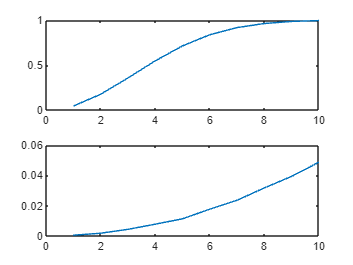

k = 0;
probArray = zeros(1,10);
m = 1000;
for n = 10:10:100
    k = k+1;
    experiencias = randi(m,n,N);
    as = true(1,N);
    for i = 1:N
        aux = experiencias(:,i);
        as(i) = length(unique(aux)) < n;
    end
    probArray(k)= sum(as)/N;
end
subplot(2,1,1);
plot(probArray)

k = 0;
probArray = zeros(1,10);
m = 100000;
for n = 10:10:100
    k = k+1;
    experiencias = randi(m,n,N);
    as = true(1,N);
    for i = 1:N
        aux = experiencias(:,i);
        as(i) = length(unique(aux)) < n;
    end
    probArray(k)= sum(as)/N;
end
subplot(2,1,2);
plot(probArray)
hold off


%% Concluimos que quanto maior o nº de dardos, maior a
%% probabilidade de pelo menos um alvo ser atingido por
%% 2 dardos, no entanto, com o aumento do nº de alvos,
%% esta probabilidade diminuiu consideravelmente
%% (ex: para 100 dardos e 1000 alvos, prob aprox igual a
%% 1, enquanto que para 100 dardos e 100000 alvos, prob
%% aprox igual a 0.05)



(d) Considere o valor de n = 100 dardos. Fac¸a as simulações necessárias para desenhar um gráfico da probabilidade da alínea (b) em função dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos. O que conclui dos resultados obtidos?

n = 100;
k = 0;
probArray = zeros(1,9);
for m = [200 500 1000 2000 5000 10000 20000 50000 100000]
    k = k+1;
    experiencias = randi(m,n,N);
    as = true(1,N);
    for i = 1:N
        aux = experiencias(:,i);
        as(i) = length(unique(aux)) < n;
    end
    probArray(k)= sum(as)/N;
end
x = [200 500 1000 2000 5000 10000 20000 50000 100000]

x =          200         500        1000        2000        5000       10000       20000       50000      100000


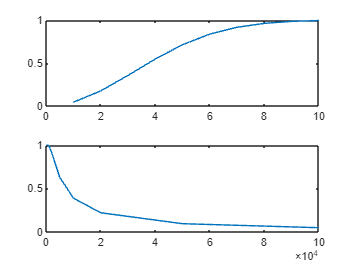

plot(x, probArray)


%% Podemos concluir o mesmo da alinea anterior: com o
%% aumento do nº de alvos, para um nº de dardos constante,
%% a probabilidade de pelo menos 1 alvo ser atingido por 2
%% ou mais dardos diminui. 

**3. Considere um array de tamanho T que serve de base à implementação de uma memória associativa (por exemplo em Java). Assuma que a função de hash devolve um valor entre 0 e T − 1 com todos os valores igualmente prováveis.**

(a) Determine por simulação a probabilidade de haver pelo menos uma colisão (pelo menos 2 keys mapeadas pela função de hash para a mesma posição do array) se forem introduzidas 10 keys num array de tamanho T = 1000.

T = 1000;
k = 10;
N = 1e5;
experiencias = randi(T, k, N);
as = true(1,N);
for i = 1:N
    column = experiencias(:,i);
    as(i) = length(unique(column))<10;
end
prob = sum(as) / N

prob = 0.0450

(b) Faça um gráfico da probabilidade da alínea (a) (estimada por simulação) em função do número de keys para todos os valores relevantes num array de tamanho T = 1000.

T = 1000;
N = 100;
tic
probArray = zeros(1, 1000);
for k = 1:1:1000
    experiencias = randi(T,k,N);
    as = true(1,N);
    for i = 1:N
        column = experiencias(:,i);
        as(i) = length(unique(column))<k;
    end
    probArray(k) = sum(as) / N;
end
plot(probArray);
toc

Elapsed time is 16.682374 seconds.


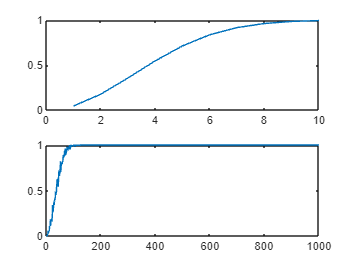

hold off

(c) Para um número de keys igual a 50, represente graficamente a variação da probabilidade (estimada por simulação) de não haver nenhuma colisão em função do tamanho T do array (assuma os tamanhos T de 100 até 1000 com incrementos de 100).

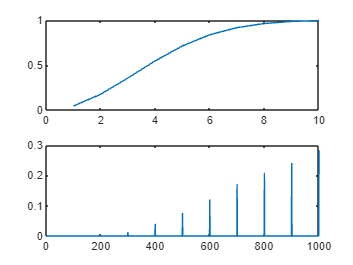

k = 50;
N = 10000;
tic
probArray = zeros(1, 1000);
arrayIterator = 1;
for T = 100:100:1000
    experiencias = randi(T,k,N);
    as = true(1,N);
    for i = 1:N
        column = experiencias(:,i);
        as(i) = length(unique(column))==k;
    end
    probArray(T) = sum(as) / N;
end

plot(probArray)

toc

Elapsed time is 5.192684 seconds.


**5. Considere um dado de seis faces numeradas de 1 a 6 lançado 2 vezes. Assuma que o dado é equilibrado (mesma probabilidade para todas as faces ficarem para cima). Considere os acontecimentos seguintes: “A – a soma dos dois valores é igual a 9”, “B – o segundo valor é par”, “C – pelo menos um dos valores é igual a 5” e “D – nenhum dos valores é igual a 1”.**

(a) Estime por simulação a probabilidade da cada um dos 4 acontecimentos.

dice = 2;
N = 100000;
values = randi(6,2,N);

Acontecimento A, a soma dos dois valores é igual a 9:

as = true(1,N);
for i=1:N
    column = values(:,i);
    as(i) = sum(column)==9;
end
%% Probabilidade da soma dos dois valores ser 9
prob = sum(as)/N

prob = 0.1103

Acontecimento B, o segundo valor é par:

as = true(1,N);
for i=1:N
    column = values(:,i);
    as(i) = rem(column(2),2)==0;
end
prob = sum(as)/N

prob = 0.5000

Acontecimento C, pelo menos um dos valores é igual a 5:

as = true(1,N);
for i=1:N
    column = values(:,i);
    as(i) = column(1) == 5 | column (2) == 5;
end
prob = sum(as)/N

prob = 0.3056

Acontecimento D, nenhum dos valores é igual a 1:

as = true(1,N);
for i=1:N
    column = values(:,i);
    as(i) = column(1) ~= 1 && column (2) ~= 1;
end
prob = sum(as)/N

prob = 0.6922

(b) Determine teoricamente se os acontecimentos A e B são independentes.

%% Para serem dois acontecimentos independentes, P(AB)
%% tem que ser igual a P(A) * P(B). Como não temos a
%% P(AB), vamos calculá-la através do que sabemos sobre A e B:
%% CP = 36 (6 lados em cada dado => 6x6)
%%
%% CF a A: (3,6);(6,3);(4,5);(5,4) => 4 CF  
%%
%% CF a B: (1,-);(2,2);(3,2);(4,2);(5,2);(6,2);
%%         (1,4);(2,4);(3,4);(4,4);(5,4);(6,4);
%%         (1,6);(2,6);(3,6);(4,6);(5,6);(6,6);
%%
%% CF a AB: (3,6);(5,4)
%% 
%% P(AB) = 2 / 36 = 0.055555556
%% P(A) * P(B) = 4/36 * 18/36 = 0.055555556

%% P(A)*P(B) = P(AB), logo os dois acontecimentos são independentes.

(c) Determine teoricamente se os acontecimentos C e D são independentes.

%% Basta aplicarmos o mesmo processo da alinea anterior:
%% CP = 36 (6 lados em cada dado => 6x6) 
%%
%% CF a C: (5,-);(-,5); ( o "-" conta como qualquer um dos 6
%% valores do dado, logo CF a D => 6+5 = 11 (nao repetir (5,5))
%%
%% CF a D: CP - (1,-);(-,1); (tendo o cuidado de
%% não repetir (1,1), ou seja: 36 - (6+5) = 25)
%%
%% CF a CD: (5,2);(5,3);(5,4);(5,5);(5,6);
%%          (2,5);(3,5);(4,5);(6,5)
%% 
%% P(CD) = 9/36 = 0.25
%% P(C) * P(D) = 11/36 * 25/36 = 0.2122

%% P(C)*P(D) ~= P(AB), logo os dois acontecimentos não são independentes.

**6. Considere uma linguagem com apenas 3 palavras {“um”, “dois”, “três”} e que permite sequências de 2 palavras. Considere que todas as sequências são equiprováveis e que as duas palavras de uma sequências podem ser iguais. As respostas às questões seguintes devem ser baseadas nos valores teóricos.**

(a) Qual a probabilidade da sequência “um dois”?

%% CF = (1,2)
%% CP = (1,1);(1,2);(1,3);(2,1);(2,2);(2,3);(3,1);(3,2);(3,3) = 9 
%% P = 1/9 = 0.(1)

(b) Qual a probabilidade de “um” aparecer pelo menos uma vez numa sequência?

%% CF = (1,-);(2,1);(3,1) = 5
%% CP = 9
%% P = 5/9 = 0.55556

(c) Qual a probabilidade de ocorrer “um” ou “dois” numa sequência?

%% A: "ocorrer um"
%% B: "ocorrer dois"
%% P(A ou B) = P(A) + P(B) - P(AB)
%% CF a A: (1,1);(1,2);(1,3);(2,1);(3,1) = 5
%% CF a B: (2,1);(2,2);(2,3);(1,2);(3,2) = 5
%% CF a AB: (1,2);(2,1) = 2
%% CP = 9
%% P(A ou B) = (5+5 - 2)/9 = 0.88889

(d) Qual o valor de P[“sequência incluir a palavra um” | “sequência inclui palavra dois”]?

%% A: "ocorrer um"
%% B: "ocorrer dois"
%% P(A|B) = P(AB) / P(B) = 2 / 5 = 0.4

**7. Considere que uma empresa tem 3 programadores (André, Bruno e Carlos) e que a probabilidade de um programa de cada um deles ter problemas (“bugs”) e o número de programas desenvolvidos assumem os valores apresentados na tabela seguinte.**

Programador Prob(“erro num programa”) programas

André                             0.01                           20

Bruno                             0.05                           30

Carlos                            0.001                         50

O Diretor da empresa seleciona de forma aleatória um dos 100 programas produzidos pelos seus 3 programadores e descobre que este contém um erro sério.

(a) Qual é a probabilidade de o programa ser do Carlos?

%% C: O programa defeituoso é do Carlos
%% S: O programa selecionado pelo Diretor é do Carlos
%% E: O programa do Carlos é defeituoso
%% O Carlos é o autor de 50 dos 100 programas produzidos,
%% portanto (ignorando para já a questão do erro), a probabilidade
%% de o pograma analizado ser do Carlos é 50/100 = 0.5. P(S) = 0.5
%% Agora, sabendo que a probabilidade de o Carlos cometer um erro
%% num programa é 0.001 (P(E) = 0.001), temos que P(C) = P(S) * P(E)
%% <=> P(C) = 0.5 * 0.001 = 0.0005
%%


(b) De quem é mais provável ser o programa?

%% Da mesma forma que calculámos P(C) na alinea anterior,
%% temos agora que calcular P(A) e P(B):
%% P(A) = 20/100 * 0.01 = 0.002
%% P(B) = 30/100 * 0.05 = 0.015
%% Como P(B) > P(A) > P(C), concluimos que é mais provável
%% o programa analizado ser do Bruno